Scientific Programming - TCGA Ovarian Cancer dataset

03 - Gene expression QC

clear;
clc;
close all;

load("results/cleaned_data.mat");

if ~exist("figures", "dir")
    mkdir("figures");
end

1. Cohort overview

size(expression_dfs)

ans =        11838         395



nMissingExpression = sum(isnan(expression_dfs(:)));

fprintf("Expression matrix: %d genes x %d patients\n", ...
    size(expression_dfs,1), size(expression_dfs,2));

Expression matrix: 11838 genes x 395 patients



fprintf("Missing expression values: %d\n", ...
    nMissingExpression);

Missing expression values: 0


The DFS expression matrix contains 11,838 genes across 395 patients, with no missing expression values.

2. Expression value distribution

allExpression = expression_dfs(:);

fprintf("Minimum expression value: %.3f\n", min(allExpression));

Minimum expression value: -7.654


fprintf("Maximum expression value: %.3f\n", max(allExpression));

Maximum expression value: 20.369


fprintf("Mean expression value: %.3f\n", mean(allExpression));

Mean expression value: -0.001


fprintf("Median expression value: %.3f\n", median(allExpression));

Median expression value: -0.031


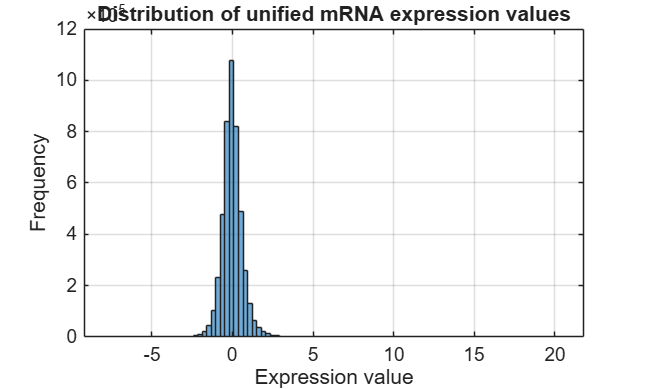


figure;
histogram(allExpression, 100);

xlabel("Expression value");
ylabel("Frequency");
title("Distribution of unified mRNA expression values");
grid on;

saveas(gcf, "figures/distribution_expression_values.png");

Expression values are strongly centered around 0, which is consistent with the scaling performed during TCGA preprocessing. Most values fall within a narrow range, although a small number of larger positive expression values are present.

3. Gene variability

geneVariance = var(expression_dfs, 0, 2);

fprintf("Median gene variance: %.3f\n", median(geneVariance));

Median gene variance: 0.299


fprintf("Minimum gene variance: %.3f\n", min(geneVariance));

Minimum gene variance: 0.006


fprintf("Maximum gene variance: %.3f\n", max(geneVariance));

Maximum gene variance: 9.153


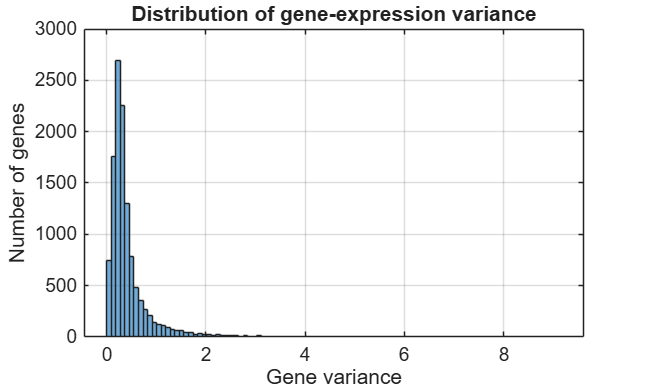


figure;
histogram(geneVariance, 100);

xlabel("Gene variance");
ylabel("Number of genes");
title("Distribution of gene-expression variance");
grid on;

saveas(gcf, "figures/distribution_gene_variability.png");

Most genes show relatively low variance across patients, while a smaller subset shows substantially higher variability. These genes are likely to contribute more strongly to difference between patients and may be candidates for filtering before downstream analysis. 

4. Low-variance filtering decision

Choose a cutoff that removes noisy genes without throwing away too much total variance.

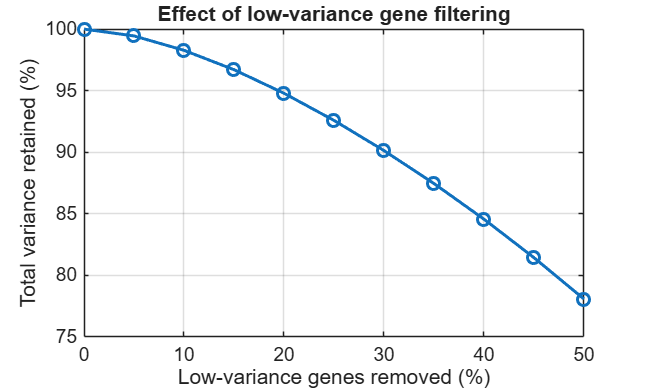

%% Visualize low-variance filtering trade-off

percentilesPlot = 0:5:50;
varianceRemaining = zeros(size(percentilesPlot));

for i = 1:numel(percentilesPlot)

    threshold = prctile(geneVariance, percentilesPlot(i));
    keep = geneVariance > threshold;

    varianceRemaining(i) = ...
        100 * sum(geneVariance(keep)) / sum(geneVariance);

end

figure;

plot(percentilesPlot, varianceRemaining, ...
    "o-", "LineWidth", 1.5);

xlabel("Low-variance genes removed (%)");
ylabel("Total variance retained (%)");
title("Effect of low-variance gene filtering");

grid on;

saveas(gcf, "figures/lowvariance_test.png");

The 20th percentile was selected as a compromise between reducing dimensionality and preserving information. By removing the lowest 20% of genes by variance we're retaining about 95% of the total expression variance.

5. Apply filtering

varianceThreshold = prctile(geneVariance, 20);

keepGenes = geneVariance > varianceThreshold;

expression_dfs_filtered = expression_dfs(keepGenes, :);
geneIDs_filtered = geneIDs(keepGenes);

fprintf("Genes before filtering: %d\n", size(expression_dfs,1));

Genes before filtering: 11838


fprintf("Genes after filtering: %d\n", size(expression_dfs_filtered,1));

Genes after filtering: 9470


fprintf("Genes removed: %d\n", sum(~keepGenes));

Genes removed: 2368


2368 genes were removed by excluding the lowest 20% of genes based on variance and 9470 genes were retained for downstream analysis. 

6. Outlier detection on the filtered matrix

%% PCA for outlier detection

X_filtered = expression_dfs_filtered';

[~, score_filtered, ~, ~, explained_filtered] = pca(X_filtered);

%% Choose number of PCs for outlier detection

cumulativeExplained = cumsum(explained_filtered);

nPC70 = find(cumulativeExplained >= 70, 1);
nPC80 = find(cumulativeExplained >= 80, 1);
nPC90 = find(cumulativeExplained >= 90, 1);

fprintf("PCs needed for 70%% variance: %d\n", nPC70);

PCs needed for 70% variance: 78


fprintf("PCs needed for 80%% variance: %d\n", nPC80);

PCs needed for 80% variance: 128


fprintf("PCs needed for 90%% variance: %d\n", nPC90);

PCs needed for 90% variance: 213


The expression data is high-dimensional, so many different patterns contribute to the differences between patients. 

%% Sensitivity of PCA-based outlier detection to number of PCs

pcChoices = [5 10 20 50 78 128];

outlierCounts = zeros(size(pcChoices));

for i = 1:numel(pcChoices)

    nPC = pcChoices(i);

    % Standardize selected PC scores
    PCscores = zscore(score_filtered(:,1:nPC));

    % Squared distance in PC space
    pcaDistance = sum(PCscores.^2, 2);

    % 99.5% chi-square threshold
    pcaThreshold = chi2inv(0.995, nPC);

    % Count outliers
    pcaOutliers = pcaDistance > pcaThreshold;

    outlierCounts(i) = sum(pcaOutliers);

    fprintf("%d PCs -> %d outliers\n", ...
        nPC, outlierCounts(i));
end

5 PCs -> 4 outliers
10 PCs -> 4 outliers
20 PCs -> 10 outliers
50 PCs -> 25 outliers
78 PCs -> 38 outliers
128 PCs -> 63 outliers


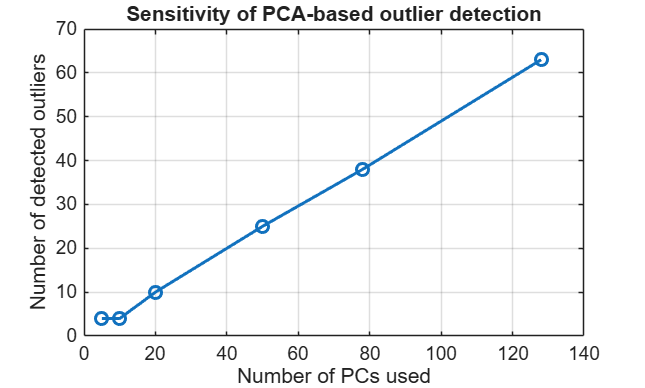


figure;

plot(pcChoices, outlierCounts, ...
    "o-", "LineWidth", 1.5);

xlabel("Number of PCs used");
ylabel("Number of detected outliers");
title("Sensitivity of PCA-based outlier detection");

grid on;

saveas(gcf, "figures/PCA_sensitivity.png");

99.5% chi-square threshold is strict, so only very extreme points should be flagged. 

Both 5 and 10 PCs detect 4 outliers. Next I check if they correspond to the same patients and compare 5 PCs vs 10 PCs.

%% Compare outliers detected using 5 and 10 PCs

PC5 = zscore(score_filtered(:,1:5));
distance5 = sum(PC5.^2, 2);
threshold5 = chi2inv(0.995, 5);
outliers5 = distance5 > threshold5;

PC10 = zscore(score_filtered(:,1:10));
distance10 = sum(PC10.^2, 2);
threshold10 = chi2inv(0.995, 10);
outliers10 = distance10 > threshold10;

fprintf("Outliers with 5 PCs: %d\n", sum(outliers5));

Outliers with 5 PCs: 4


fprintf("Outliers with 10 PCs: %d\n", sum(outliers10));

Outliers with 10 PCs: 4


fprintf("Same patients detected by both: %d\n", ...
    sum(outliers5 & outliers10));

Same patients detected by both: 2



clinical_dfs.SAMPLE_ID(outliers5 & outliers10)

ans = 2×1 cell array
    {'TCGA-25-1877-01'}
    {'TCGA-29-1775-01'}


PCA-based outlier detection was sensitive to the number of PCs used. Using 5 and 10 PCs identified 4 candidate outliers, but only 2 patients were shared between both sets. So, PCA-based outliers are treated as candidates only and were not automatically removed. 

Correlation-based outlier detection:

% Correlation between patient expression profiles
sampleCorrelation = corr(expression_dfs_filtered);

% Ignore correlation of each sample with itself
sampleCorrelation(1:size(sampleCorrelation,1)+1:end) = NaN;

% Median correlation of each patient with all other patients
medianSampleCorrelation = median(sampleCorrelation, 2, "omitnan");

% Robust lower threshold
correlationThreshold = ...
    median(medianSampleCorrelation) - ...
    3 * mad(medianSampleCorrelation, 1);

candidateOutliers = medianSampleCorrelation < correlationThreshold;

fprintf("Outlier threshold: %.3f\n", correlationThreshold);

Outlier threshold: -0.027


fprintf("Potential outliers: %d\n", sum(candidateOutliers));

Potential outliers: 29


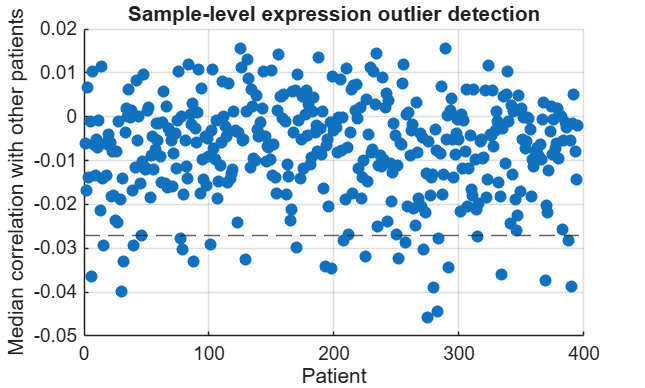


figure;

scatter(1:numel(medianSampleCorrelation), ...
        medianSampleCorrelation, ...
        "filled");

hold on;
yline(correlationThreshold, '--');
hold off;

xlabel("Patient");
ylabel("Median correlation with other patients");
title("Sample-level expression outlier detection");

grid on;

saveas(gcf, "figures/samplelevel_outlierdetection.png");


%% Inspect correlation-based candidate outliers

fprintf("Potential correlation outliers: %d\n", ...
    sum(candidateOutliers));

Potential correlation outliers: 29



outlierIDs = clinical_dfs.SAMPLE_ID(candidateOutliers);

disp(outlierIDs)

    {'TCGA-04-1347-01'}
    {'TCGA-04-1514-01'}
    {'TCGA-09-0364-01'}
    {'TCGA-09-0369-01'}
    {'TCGA-09-2049-01'}
    {'TCGA-10-0927-01'}
    {'TCGA-13-0800-01'}
    {'TCGA-13-0802-01'}
    {'TCGA-13-0888-01'}
    {'TCGA-13-0908-01'}
    {'TCGA-13-1494-01'}
    {'TCGA-23-1121-01'}
    {'TCGA-24-1425-01'}
    {'TCGA-24-1434-01'}
    {'TCGA-24-1544-01'}
    {'TCGA-24-1567-01'}
    {'TCGA-24-2038-01'}
    {'TCGA-24-2280-01'}
    {'TCGA-25-1328-01'}
    {'TCGA-25-1626-01'}
    {'TCGA-25-1634-01'}
    {'TCGA-25-1871-01'}
    {'TCGA-25-1877-01'}
    {'TCGA-25-2408-01'}
    {'TCGA-29-1774-01'}
    {'TCGA-30-1892-01'}
    {'TCGA-61-1900-01'}
    {'TCGA-61-2095-01'}
    {'TCGA-61-2098-01'}



Correlation-based screening identified 29 patients with unusually low median correlation to the rest of the cohort. Because this was substantially more than the number identified by the PCA-based approach, these samples were considered potential outliers rather than automatically excluded.

Compare the two outlier methods: 

fprintf("Correlation-based outliers: %d\n", sum(candidateOutliers));

Correlation-based outliers: 29



fprintf("Overlap with 5-PC outliers: %d\n", ...
    sum(candidateOutliers & outliers5));

Overlap with 5-PC outliers: 2



fprintf("Overlap with 10-PC outliers: %d\n", ...
    sum(candidateOutliers & outliers10));

Overlap with 10-PC outliers: 1



fprintf("Flagged by all three methods: %d\n", ...
    sum(candidateOutliers & outliers5 & outliers10));

Flagged by all three methods: 1


Outlier detection produced inconsistent results across methods. PCA-based detection was sensitive to the number of PCs used, while correlation-based screening identified 29 candidate outliers. Only one patient was consistently flagged across the approaches. Because there was insufficient evidence that these samples represented technical outliers rather than genuine biological variation, no patients were removed.

7. PCA of gene expression data

fprintf("Variance explained by PC1: %.2f%%\n", explained_filtered(1));

Variance explained by PC1: 8.15%


fprintf("Variance explained by PC2: %.2f%%\n", explained_filtered(2));

Variance explained by PC2: 5.32%


fprintf("Variance explained by first 10 PCs: %.2f%%\n", ...
    sum(explained_filtered(1:10)));

Variance explained by first 10 PCs: 33.99%


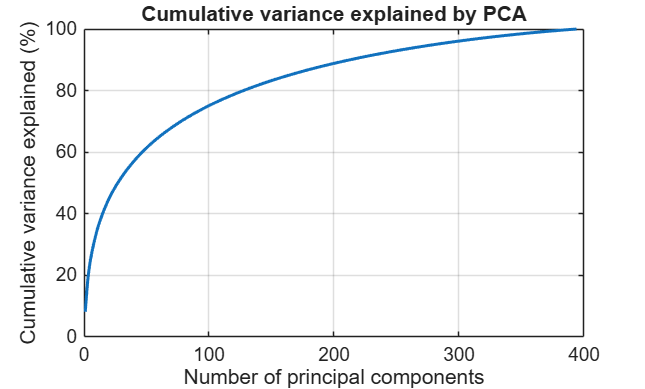


figure;
plot(cumsum(explained_filtered), "LineWidth", 1.5);

xlabel("Number of principal components");
ylabel("Cumulative variance explained (%)");
title("Cumulative variance explained by PCA");

grid on;

saveas(gcf, "figures/cumulativevariance_PCA.png");

Variance is spread across many PCs, rather than dominated by just the first PCs. 

PCA colored by DFS event status

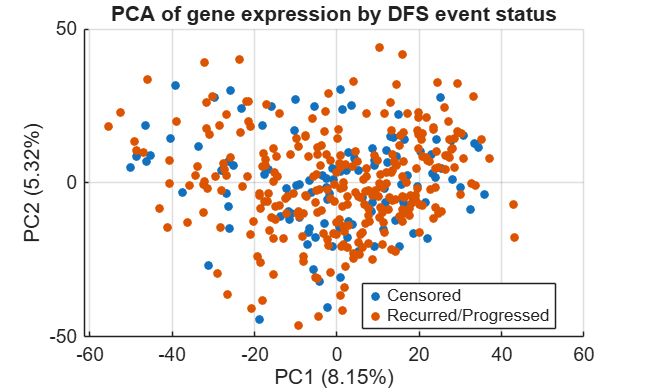

%% PCA1 vs PCA2
figure;

gscatter( ...
    score_filtered(:,1), ...
    score_filtered(:,2), ...
    dfsEvent);

xlabel(sprintf("PC1 (%.2f%%)", explained_filtered(1)));
ylabel(sprintf("PC2 (%.2f%%)", explained_filtered(2)));

title("PCA of gene expression by DFS event status");

legend( ...
    "Censored", ...
    "Recurred/Progressed", ...
    "Location","best");

grid on;

saveas(gcf, "figures/PCA_geneexpression_DFS.png");

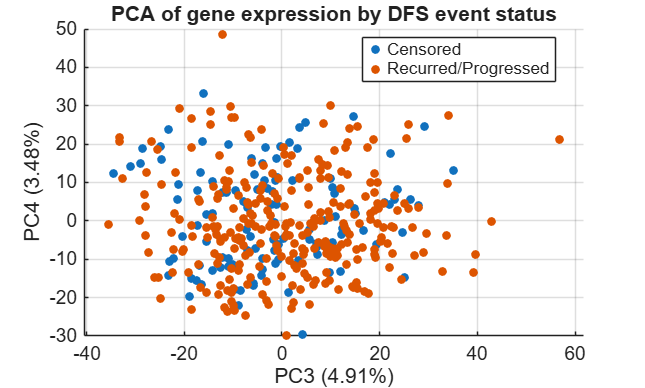


%% PCA: PC3 vs PC4

figure;

gscatter( ...
    score_filtered(:,3), ...
    score_filtered(:,4), ...
    dfsEvent);

xlabel(sprintf("PC3 (%.2f%%)", explained_filtered(3)));
ylabel(sprintf("PC4 (%.2f%%)", explained_filtered(4)));

title("PCA of gene expression by DFS event status");

legend( ...
    "Censored", ...
    "Recurred/Progressed", ...
    "Location","best");

grid on;

PCA scatterplot

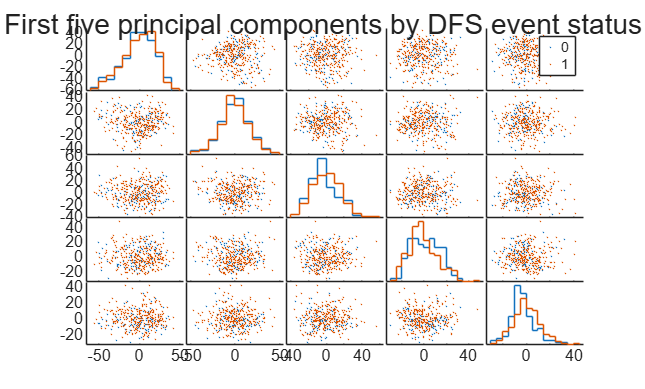

%% Pairwise visualization of first 5 principal components

figure;

gplotmatrix( ...
    score_filtered(:,1:5), ...
    [], ...
    dfsEvent);

sgtitle("First five principal components by DFS event status");

saveas(gcf, "figures/PCA_DFS_5PCs.png");

Pairwise visualization of the first five PCs shows substantial overlap between censored and recurrent/progressed patients across all component combinations. No clear clustering by DFS event status is apparent.

The first five PCs were used for pairwise visualization because they represent the leading directions of variation in the expression data while keeping the number of plots manageable. This visualization was exploratory and was not used to define the final predictive model.

8. Cox regression for the first 10 components

nPC = 10;

coxResults = table( ...
    (1:nPC)', ...
    explained_filtered(1:nPC), ...
    nan(nPC,1), ...
    nan(nPC,1), ...
    nan(nPC,1), ...
    nan(nPC,1), ...
    'VariableNames', ...
    {'PC','VarianceExplained','HazardRatio','Lower95CI','Upper95CI','PValue'});

for i = 1:nPC

    predictor = zscore(score_filtered(:,i));

    [b,~,~,stats] = coxphfit( ...
        predictor, ...
        clinical_dfs.DFS_MONTHS, ...
        'Censoring', ~dfsEvent);

    coxResults.HazardRatio(i) = exp(b);
    coxResults.Lower95CI(i) = exp(b - 1.96*stats.se);
    coxResults.Upper95CI(i) = exp(b + 1.96*stats.se);
    coxResults.PValue(i) = stats.p;

end

%% Multiple-testing correction

coxResults.FDR = mafdr(coxResults.PValue, ...
    "BHFDR", true);

disp(coxResults)

    PC    VarianceExplained    HazardRatio    Lower95CI    Upper95CI     PValue       FDR  
    __    _________________    ___________    _________    _________    ________    _______

     1         8.1534            0.99269       0.88356       1.1153      0.90178     0.9827
     2         5.3202             1.0071       0.89872       1.1286      0.90299     0.9827
     3         4.9113             1.1103       0.99057       1.2445     0.072287    0.24096
     4           3.48             1.0014       0.88495       1.1331       0.9827     0.9827
     5         2.7624             1.1756        1.0469       1.3201      0.00625     0.0625
     6         2.1948             1.0468       0.93705       1.1695      0.41806    0.83611
     7         2.0033    

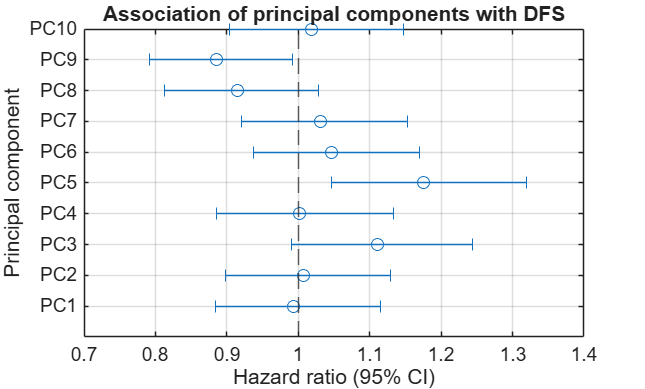

%% Forest plot of Cox regression results for PCs

figure;

errorbar( ...
    coxResults.HazardRatio, ...
    coxResults.PC, ...
    coxResults.HazardRatio - coxResults.Lower95CI, ...
    coxResults.Upper95CI - coxResults.HazardRatio, ...
    'horizontal', ...
    'o');

hold on;

xline(1, '--');

yticks(1:nPC);
yticklabels("PC" + string(1:nPC));

xlabel("Hazard ratio (95% CI)");
ylabel("Principal component");
title("Association of principal components with DFS");

grid on;
hold off;

saveas(gcf, "figures/forestplot_PCs_DFS.png");

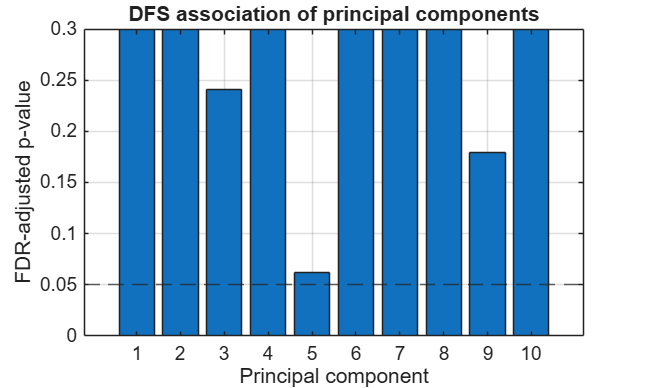

%% FDR-adjusted p-values for PCs

figure;

bar(coxResults.PC, coxResults.FDR);

hold on;
yline(0.05, '--');
hold off;

xlabel("Principal component");
ylabel("FDR-adjusted p-value");
title("DFS association of principal components");

xticks(1:nPC);
ylim([0 0.3]);
grid on;

saveas(gcf, "figures/PCs_DFS_association.png");

PC5 was nominally significant before correction, but after FDR correction it was no longer significant (FDR ≈ 0.063). None of the first 10 PCs remained significant after correction.

The first 10 PCs were examined as an exploratory screen of whether major expression patterns were associated with DFS. This analysis was not used as the final model-selection procedure.

9. Box plot of PC5 by DFS event status

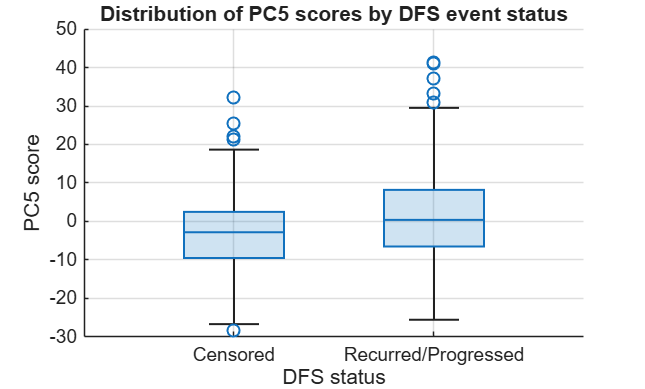

dfsGroup = categorical(dfsEvent, ...
    [0 1], ...
    {'Censored','Recurred/Progressed'});

figure;

boxchart(dfsGroup, score_filtered(:,5));

xlabel("DFS status");
ylabel("PC5 score");
title("Distribution of PC5 scores by DFS event status");

grid on;

saveas(gcf, "figures/boxplot_PC5_DFS.png");

PC5 scores tended to be higher in recurrent/progressed patients than in censored patients, although the distributions overlapped substantially. The overlap indicates that PC5 alone does not clearly separate the two outcome groups.

10. UMAP visualization

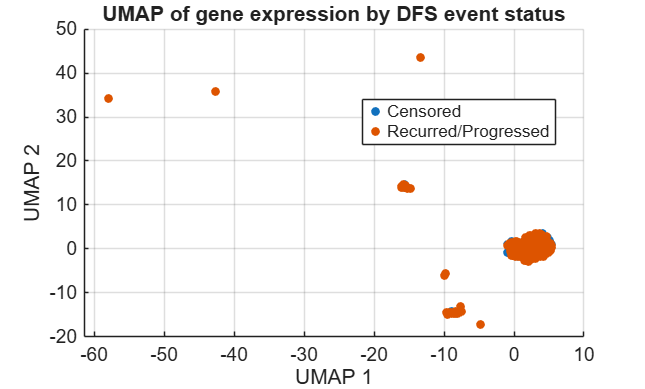

% UMAP uses patients as rows and genes as columns
rng(1);   % for reproducibility

Y_umap = umap(X_filtered);

figure;
gscatter(Y_umap(:,1), Y_umap(:,2), dfsEvent);

xlabel("UMAP 1");
ylabel("UMAP 2");
title("UMAP of gene expression by DFS event status");

legend( ...
    "Censored", ...
    "Recurred/Progressed", ...
    "Location","best");

grid on;

saveas(gcf, "figures/UMAP_geneexpression_DFS.png");

UMAP directly on 9470 genes, so it can be dominated by noisy or extreme directions. 

Use the first 50 PCs:

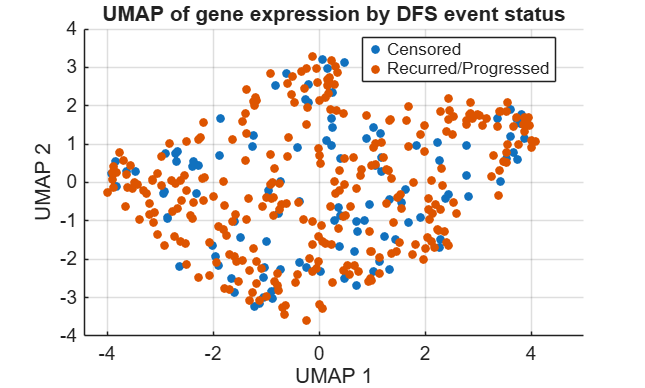

%% UMAP after PCA pre-reduction

rng(1);

X_umap = score_filtered(:,1:50);

Y_umap = umap(X_umap);

figure;

gscatter( ...
    Y_umap(:,1), ...
    Y_umap(:,2), ...
    dfsEvent);

xlabel("UMAP 1");
ylabel("UMAP 2");
title("UMAP of gene expression by DFS event status");

legend( ...
    "Censored", ...
    "Recurred/Progressed", ...
    "Location","best");

grid on;

saveas(gcf, "figures/UMAP_geneexpression_DFS_reduced.png");

Before UMAP, the expression data were reduced to the first 50 principal components. This was done to remove very low-variance dimensions and reduce computational burden while retaining the major structure of the gene-expression data. Fifty PCs were used as a practical compromise: enough components to preserve substantial biological variation, while avoiding direct UMAP fitting on thousands of genes.

UMAP visualization of the filtered gene-expression data also showed substantial overlap between censored and recurred/progressed patients, with no clear cluster separation by DFS event status. This suggests that the overall expression structure is not strongly driven by DFS group membership.

UMAP colored by residual disease

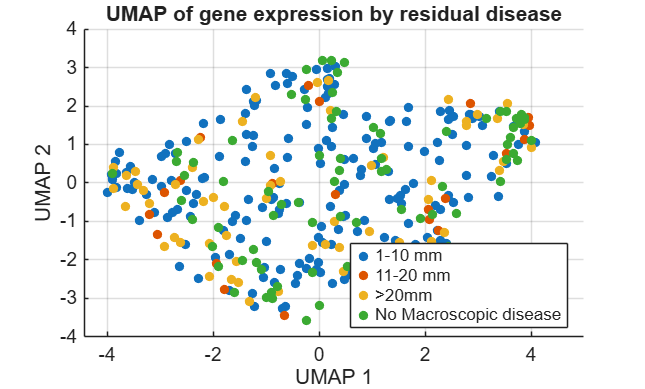

residualDisease = categorical(clinical_dfs.TUMOR_RESIDUAL_DISEASE);

validResidual = string(clinical_dfs.TUMOR_RESIDUAL_DISEASE) ~= "NA";

figure;

gscatter( ...
    Y_umap(validResidual,1), ...
    Y_umap(validResidual,2), ...
    residualDisease(validResidual));

xlabel("UMAP 1");
ylabel("UMAP 2");
title("UMAP of gene expression by residual disease");

legend("Location","best");
grid on;

saveas(gcf, "figures/UMAP_geneexpression_residualdisease.png");

UMAP colored by residual disease showed substantial overlap between clinical groups, with no clear clustering according to residual tumor burden. This suggests that the major nonlinear structure in gene-expression data is not strongly determined by residual disease category.

UMAP colored by grade

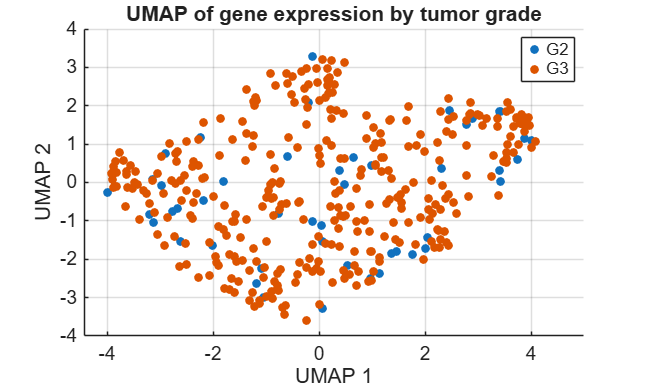

grade = categorical(clinical_dfs.GRADE);

validGrade = string(clinical_dfs.GRADE) ~= "NA";

figure;

gscatter( ...
    Y_umap(validGrade,1), ...
    Y_umap(validGrade,2), ...
    grade(validGrade));

xlabel("UMAP 1");
ylabel("UMAP 2");
title("UMAP of gene expression by tumor grade");

legend("Location","best");
grid on;
saveas(gcf, "figures/UMAP_geneexpression_tumorgrade.png");

UMAP colored by tumor grade showed substantial overlap between G2 and G3 tumors, with no clear grade-specific clustering in the gene-expression space. This suggests that tumor grade does not correspond to a strong global expression pattern in this cohort.

UMAP by tumor stage group

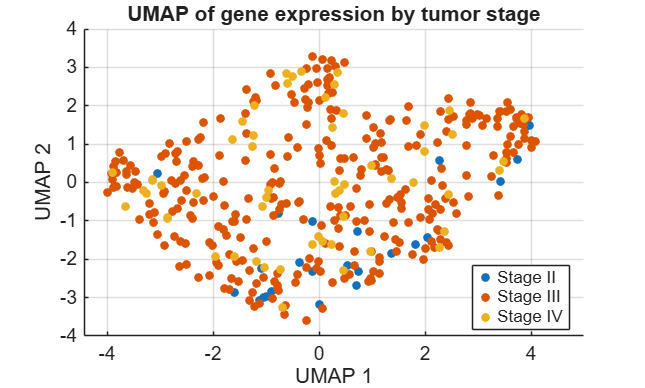

stageRaw = string(clinical_dfs.TUMOR_STAGE_2009);

stageGroup = strings(size(stageRaw));

stageGroup(ismember(stageRaw, ["IIA","IIB","IIC"])) = "Stage II";
stageGroup(ismember(stageRaw, ["IIIA","IIIB","IIIC"])) = "Stage III";
stageGroup(stageRaw == "IV") = "Stage IV";

validStage = stageRaw ~= "NA";

stageGroup = categorical(stageGroup(validStage));

figure;

gscatter( ...
    Y_umap(validStage,1), ...
    Y_umap(validStage,2), ...
    stageGroup);

xlabel("UMAP 1");
ylabel("UMAP 2");
title("UMAP of gene expression by tumor stage");

legend("Location","best");
grid on;
saveas(gcf, "figures/UMAP_geneexpression_tumorstage.png");

UMAP colored by tumor stage showed substantial overlap between Stage II, III and IV tumors, with no clear stage-specific clustering in the gene-expression space. This suggests that tumor stage is not the main driver of the global expression structure in this cohort.

11. Heatmap with hierarchical clustering 

50 most variable genes

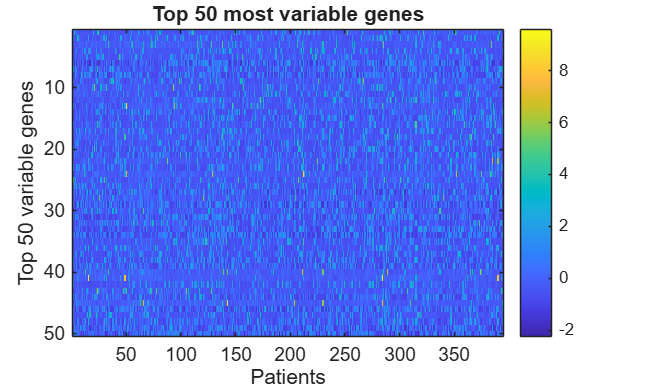

filteredGeneVariance = var(expression_dfs_filtered, 0, 2);

[~, idxTop] = maxk(filteredGeneVariance, 50);

topExpression = expression_dfs_filtered(idxTop, :);

% Standardize each gene across patient
topExpressionZ = zscore(topExpression, 0, 2);

figure;

imagesc(topExpressionZ);

xlabel("Patients");
ylabel("Top 50 variable genes");
title("Top 50 most variable genes");

colorbar;
saveas(gcf, "figures/heatmap_50variablegenes.png");

Very noisy heatmap, so next step is cluster the patients and the 50 genes:

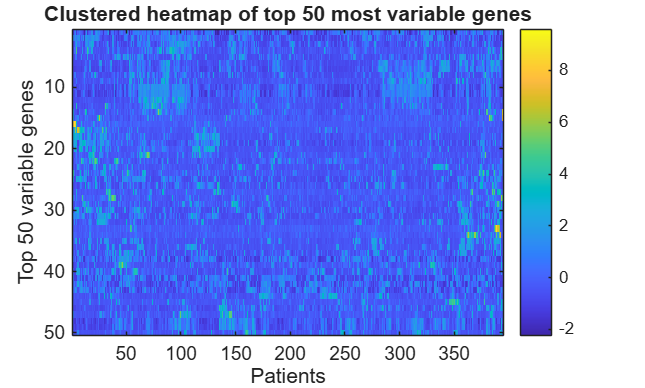

% Cluster patients
patientDistance = pdist(topExpressionZ', 'euclidean');
patientTree = linkage(patientDistance, 'average');
patientOrder = optimalleaforder(patientTree, patientDistance);

% Cluster genes
geneDistance = pdist(topExpressionZ, 'euclidean');
geneTree = linkage(geneDistance, 'average');
geneOrder = optimalleaforder(geneTree, geneDistance);

% Reorder matrix
topExpressionZ_clustered = ...
    topExpressionZ(geneOrder, patientOrder);

figure;

imagesc(topExpressionZ_clustered);

xlabel("Patients");
ylabel("Top 50 variable genes");
title("Clustered heatmap of top 50 most variable genes");

colorbar;
saveas(gcf, "figures/clusteredheatmap_50variablegenes.png");

Add DFS annotation:

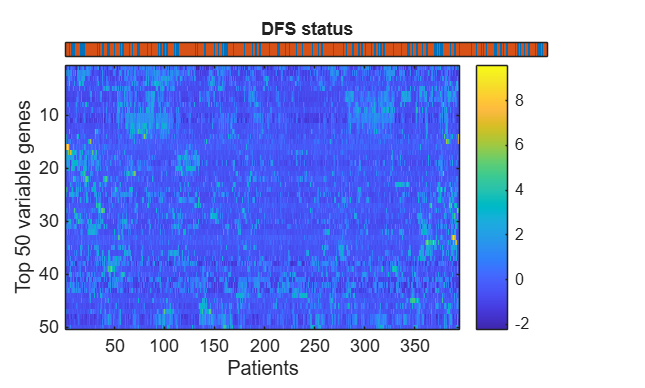

% Reorder DFS status using clustered patient order
dfsClustered = dfsEvent(patientOrder);

% Main heatmap
figure;

ax1 = axes('Position',[0.1 0.15 0.75 0.68]);

imagesc(ax1, topExpressionZ_clustered);

xlabel(ax1, "Patients");
ylabel(ax1, "Top 50 variable genes");

colorbar(ax1);

% DFS annotation strip
ax2 = axes('Position',[0.1 0.85 0.75 0.04]);

imagesc(ax2, dfsClustered');

yticks(ax2, []);
xticks(ax2, []);

title(ax2, "DFS status");

colormap(ax2, [0 0.4470 0.7410; 0.8500 0.3250 0.0980]);
saveas(gcf, "figures/clusteredheatmap_50variablegenes_DFS.png");

Hierarchical clustering of the 50 most variable genes did not reveal clear patient groups corresponding to DFS status. Censored and recurrent/progressed patients were interspersed across the expression-based clusters, consistent with the PCA and UMAP results showing no strong global separation by DFS outcome.